# Load data


dataPath = fullfile("Data/location_data (1)");
dataDirectory = dir(dataPath);
bikeData = [];

% for i = 3:length(dataDirectory)
for i = 3:4
    baseFileName = dataDirectory(i).name;
    fullFileName = fullfile(dataPath, baseFileName);
    table = readtable(fullFileName);
    bikeData{end+1} = table(:, [2, 5:15, 17]);
end


for i = 1:length(bikeData)
    currentData = bikeData{i};

    beginx = currentData.longitude(1);
    beginy = currentData.latitude(1);
end

Now, the GPS coordinates are converted to (x, y) coordinates.

## Calculating xy coordinates and rotating bike paths

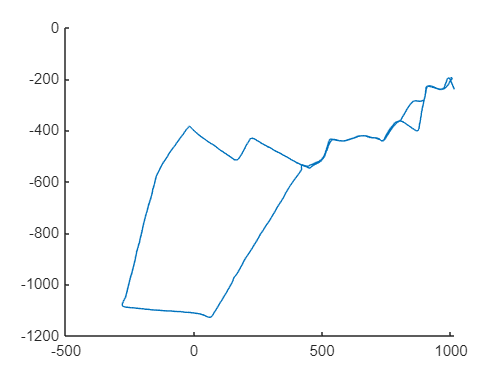

alt = 30;  % 30 meters is an approximate altitude in Enschede
origin = [bikeData{1}.latitude(1), bikeData{1}.longitude(1), alt];

for i = 1:length(bikeData)
    currentData = bikeData{i};
    [x,y] = latlon2local(currentData.latitude, currentData.longitude, alt, origin);
    bikeData{i}.("x") = x;
    bikeData{i}.("y") = y;
end
% hold off

newCoordinates = line(bikeData{2}.x, bikeData{2}.y);
rotate(newCoordinates, [0 0 1], -90);

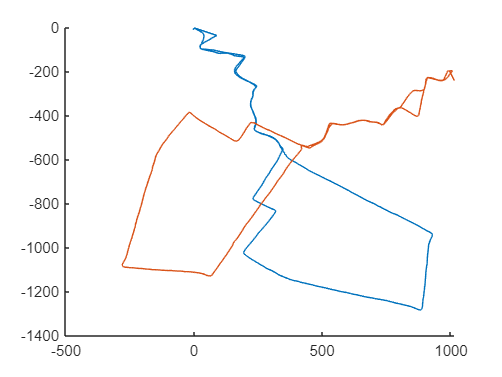

bikeData{2}.x = transpose(newCoordinates.XData);
bikeData{2}.y = transpose(newCoordinates.YData);

figure

hold on
for i = 1:length(bikeData)
    plot(bikeData{i}.x, bikeData{i}.y)
end
hold off




for i = 1:length(bikeData)
    bikeData{i}.("heading") = zeros(height(bikeData{i}), 1);
    for j = 2:height(bikeData{i})
        currentPos = table2array(bikeData{i}(j, ["x", "y"]));
        previousPos = table2array(bikeData{i}(j-1, ["x", "y"]));
        if currentPos ~= previousPos
            heading = [currentPos(1) - previousPos(1), ...
                currentPos(2) - previousPos(2)];

            angle = rad2deg(atan2(heading(2), heading(1)));
            bikeData{i}.heading(j) = angle;
        else
            bikeData{i}.heading(j) = bikeData{i}.heading(j-1);
        end
    end
end

Determine which messages the nodes should receive

## Creating grid of listener nodes

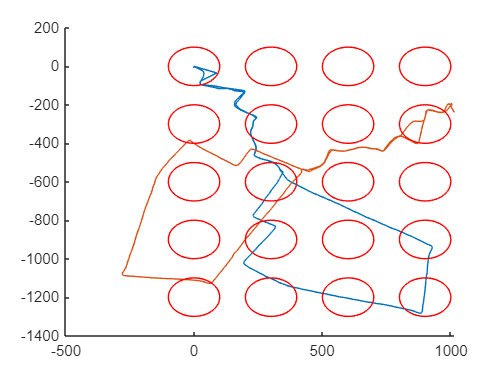

networkSimulator = wirelessNetworkSimulator.init;

amountX = 3;
amountY = 4;

function [nodes, receivedData] = createGrid(amountX, amountY)
    distance = 300;
    nodes = [];
    storageArray = [];
    nodeNames = string;
    nodeID = 1;
    % receivedData = dictionary;

    for y = 0:distance:amountY*distance
        for x = 0:distance:amountX*distance
            config = bluetoothMeshProfileConfig(ElementAddress=dec2hex(nodeID,4),...
                NetworkTransmissions=1);
            node = bluetoothLENode("broadcaster-observer", Name="Grid" + nodeID);
            node.Position = [x -y 0];
            nodes{end+1} = node;
            storageArray{nodeID} = uint32.empty;
            nodeNames(nodeID) = node.Name;
            nodeID = nodeID + 1;
        end
    end

   receivedData = dictionary(nodeNames, storageArray);
end

global receivedData;
[grid, receivedData] = createGrid(amountX, amountY);



function h = circle(x,y,r)
    hold on
    th = 0:pi/50:2*pi;
    xunit = r * cos(th) + x;
    yunit = r * sin(th) + y;
    h = plot(xunit, yunit, Color="red", MarkerSize=0.1);
    hold off
end

hold on
for i=1:length(grid)
    circle(grid{i}.Position(1), grid{i}.Position(2), 100);
end
hold off

## Determine which messages each listener node should receive

function x = inRange(position1, position2)
    % distance = sqrt((position1(1) - position2(1))^2 + (position1(2) - position2(2))^2);
    distance = pdist2(position1, position2);
    x = distance <= 100;
end

function toReceive = determineToReceive(grid, amountX, amountY, bikeData)
    filePath = "Output\messagesToReceive\grid" + amountX + "x" + amountY + ".mat"
    if false
    % if isfile(filePath)
        load(filePath, "toReceive")
    else

        toReceive = cell([1 length(grid)]);
        
        for k = 1:length(grid)
            % receive = cell([1 (length(bikeData)*height(bikeData{1}))]);
            toReceive{k} = [];
            for i = 1:length(bikeData)
                % i=1;
                % for j = 1:height(bikeData{i})
                for j = 400:750
                    messagePosition = [bikeData{i}.x(j) bikeData{i}.y(j)];
                    if inRange(grid{k}.Position([1 2]), messagePosition)
                        toReceive{k}(end + 1) = bikeData{i}.x_id(j);                        
                    end
                end
            end
            % toReceive{k} = receive;
        end
        % save(filePath, "toReceive")
    end
end

toReceive = determineToReceive(grid, amountX, amountY, bikeData);

filePath = "Output\messagesToReceive\grid3x4.mat"

Setup simulation

## Setup simulation

numNodes = 3;

config = bluetoothMeshProfileConfig(ElementAddress=dec2hex(length(grid)+1, 4),...
        NetworkTransmissions=1);

config.Relay = false;


bike1 = bluetoothLENode("broadcaster-observer", Name="Bike1", MeshConfig=config);
bike2 = bluetoothLENode("broadcaster-observer", Name="Bike2", MeshConfig=config);

receivedData(bike1.Name) = {uint32.empty};
receivedData(bike2.Name) = {uint32.empty};


bikes = {bike1 bike2};

global traffic
traffic = dictionary;

for i = 1:length(bikes)
    traffic{bikes{i}.Name} = networkTrafficOnOff(OnTime=0.02, OffTime=0.08, PacketSize=8, GeneratePacket=true, DataRate=1000);
    addTrafficSource(bikes{i}, traffic{bikes{i}.Name}, ...
        SourceAddress=bikes{i}.MeshConfig.ElementAddress, ...
        DestinationAddress=grid{5}.MeshConfig.ElementAddress);
end



% traffic{bike2.Name} = networkTrafficOnOff(OnTime=0.02, OffTime=inf, PacketSize=8, GeneratePacket=true, DataRate=1000);
% addTrafficSource(bike2, traffic, ...
%     SourceAddress=bike2.MeshConfig.ElementAddress, ...
%     DestinationAddress=grid{5}.MeshConfig.ElementAddress);

simulationData = struct;
simulationData.bikeData = bikeData;
simulationData.simulator = networkSimulator;
simulationData.bikes = bikes;
simulationData.traffic = traffic;
global iteration
iteration = 400;

Create listener to process received data

function processData(Node, EventData)
    global receivedData;
    % fprintf("Message received")
    message = EventData.Data.Message;

    received_id = typecast(uint8(transpose(message)), 'uint32');

    % dataReceived = receivedData(Node.Name);
    % dataReceived(end+1) = received_id;
    receivedData{Node.Name}(end+1) = received_id(1);
end

for i = 1:length(grid)
    addlistener(grid{i}, "MeshAppDataReceived", @processData);
end
% 
% addlistener(grid{8}, "MeshAppDataReceived", @processData);
% % addlistener(bike1, "MeshAppDataReceived", @processData);


Create listener for sending data

function transmitData(node, EventData)
    global traffic
    % traffic{node.Name}.GeneratePacket = false;
    traffic{node.Name}.OffTime = 1;
end

% addlistener(bike1, "PacketTransmissionStarted", @transmitData);
% addlistener(bike2, "PacketTransmissionStarted", @transmitData);


Create function which sets position of the bike 

function sendData(~, userData)
    global iteration;

    for i = 1:(length(userData.bikes))
        userData.bikes{i}.Position = [userData.bikeData{i}.x(iteration) ...
            userData.bikeData{i}.y(iteration) 0];
        
        id = uint32(userData.bikeData{i}.x_id(iteration));
        bytes = typecast(id, "uint8");
        userData.traffic{userData.bikes{i}.Name}.ApplicationData = bytes;
        % userData.traffic{userData.bikes{i}.Name}.OffTime = 0;
    end

    
    iteration = iteration + 1;
end


addNodes(networkSimulator, bikes);
addNodes(networkSimulator, grid);
scheduleAction(networkSimulator, @sendData, simulationData, 0, 0.1);

Bluetooth messages will now be simulated

## Run simulation

simulationTime = 5;

startTime = datetime;
fprintf("%s: Starting simulation", startTime)

10-Jan-2025 16:43:36: Starting simulation

run(networkSimulator,simulationTime);
endTime = datetime;
fprintf("%s: Simulation ended", endTime)

10-Jan-2025 16:46:32: Simulation ended



bike1Stats = statistics(bike1)

bike1Stats = struct with fields:
         Name: "Bike1"
           ID: 21
          App: [1×1 struct]
    Transport: [1×1 struct]
      Network: [1×1 struct]
           LL: [1×1 struct]
          PHY: [1×1 struct]


gridStats = statistics(grid{1})

gridStats = struct with fields:
         Name: "Grid1"
           ID: 1
          App: [1×1 struct]
    Transport: [1×1 struct]
      Network: [1×1 struct]
           LL: [1×1 struct]
          PHY: [1×1 struct]


grid2Stats = statistics(grid{2})

grid2Stats = struct with fields:
         Name: "Grid2"
           ID: 2
          App: [1×1 struct]
    Transport: [1×1 struct]
      Network: [1×1 struct]
           LL: [1×1 struct]
          PHY: [1×1 struct]


iteration

iteration = 751

## Now we will check whether all messages are received correctly.

received = unique(receivedData{grid{1}.Name})

received = 1×247 uint32 row vector
   11444   11445   11446   11447   11448   11449   11450   11451   11452   11453   11454   11455   11456   11457   11458   11459   11460   11461   11462   11463   11464   11465   11466   11467   11468   11469   11470   11471   11472   11473   11474   11475   11476   11477   11478   11479   11480   11481   11482   11483   11484   11485   11486   11487   11488   11489   11490   11491   11492   11493


% received = receivedData{grid{1}.Name}
toReceive{1}

ans =        11444       11445       11446       11447       11448       11449       11450       11451       11452       11453       11454       11455       11456       11457       11458       11459       11460       11461       11462       11463       11464       11465       11466       11467       11468       11469       11470       11471       11472       11473       11474       11475       11476       11477       11478       11479       11480       11481       11482       11483       11484       11485       11486       11487       11488       11489       11490       11491       11492       11493


correctlyReceived = 0;

for i=1:length(toReceive{1})
    if ismember(toReceive{1}(i), receivedData{grid{1}.Name})
        correctlyReceived = correctlyReceived + 1;
    end
end

fractionCorrect = correctlyReceived/length(toReceive{1})

fractionCorrect = 0.8662


received = unique(receivedData{grid{8}.Name})

received = 1×14 uint32 row vector
   23745   23746   23747   23748   23749   23751   23752   23753   23754   23756   23757   23758   23759   23760


toReceive{8}

ans =        23778       23779       23780       23781       23782       23783       23784       23785       23786       23787       23788       23789       23790       23791       23792       23793       23794


correctlyReceived = 0;
for i=1:length(toReceive{8})
    if ismember(toReceive{8}(i), receivedData{grid{8}.Name})
        correctlyReceived = correctlyReceived + 1;
    end
end

fractionCorrect = correctlyReceived/length(toReceive{8})

fractionCorrect = 0

Now we will simulate event-based broadcasting

maxGenerateTime = 5000; % the maximum time between two transmitted messages, which is 5000 ms
minDistance = 4; % minimum change in distance after last transmitted message, which is 4 meters
minSpeedChange = 5; % minimum speed change between after last transmitted message, which is 5 m/s
minheadingChange = 4; % minimum change in heading after last transmitted message, which is 4 degrees

% function toSend = determinePacketsToSend(bikeData)
%     lastMessage = bikeData(1, :);
%     toSend = [lastMessage];
% 
% 
%     for i = 2:length(bikeData)
%         if bikeData.timestamp_ms(1) >= lastMessage.timestamp_ms
%             lastMessage = bikeData(i, :);
%             toSend{end + 1} = lastMessage;
%         elseif pdist2(bikeData{i,["x","y"]}, lastMessage{["x", "y"]}) >= minDistance
%             lastMessage = bikeData(i, :);
%             toSend{end + 1} = lastMessage;
%         elseif abs(bikeData.velocity(i) - lastMessage.velocity) >= minSpeedChange
%             lastMessage = bikeData(i, :);
%             toSend{end + 1} = lastMessage;
%         elseif 
%         end
%     end
% end